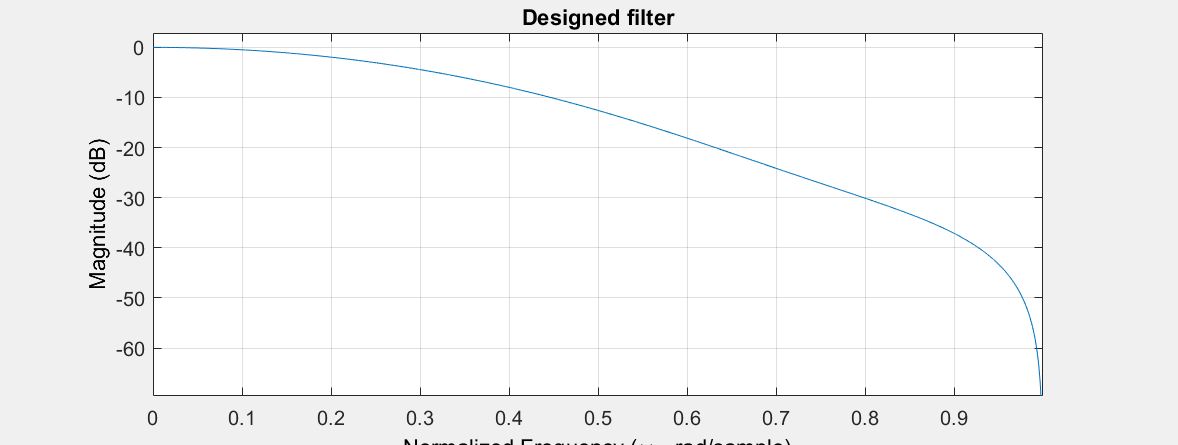

clear all;
close all;
%% Filter Specifications
M=5;
fs=2000;
fc=100;
wc=2*fc/fs;
h = fir1(M,wc);
h_fixed=fi(h, 1, 8, 7);
%% Plot filter gain vs frequency response
fvtool(h);
title('Designed filter');

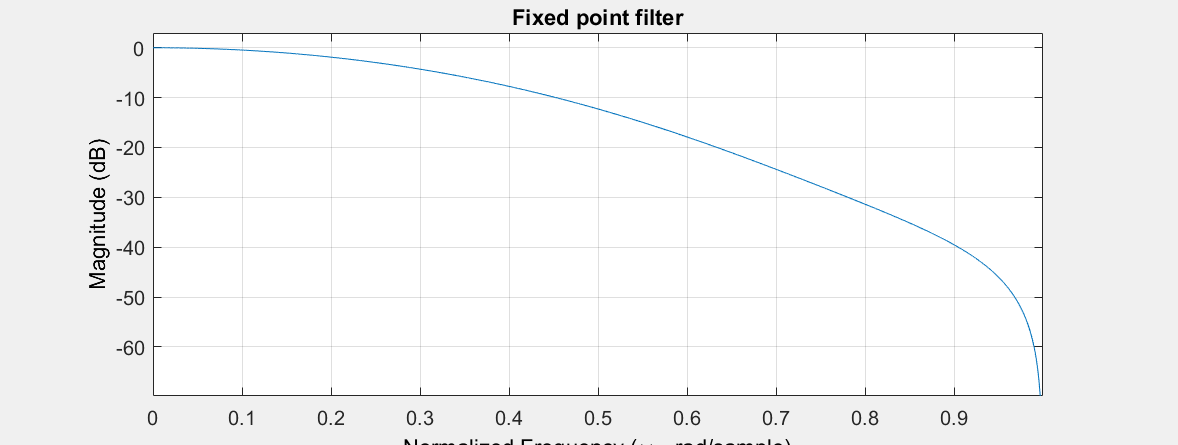


fvtool(h_fixed);
title('Fixed point filter');

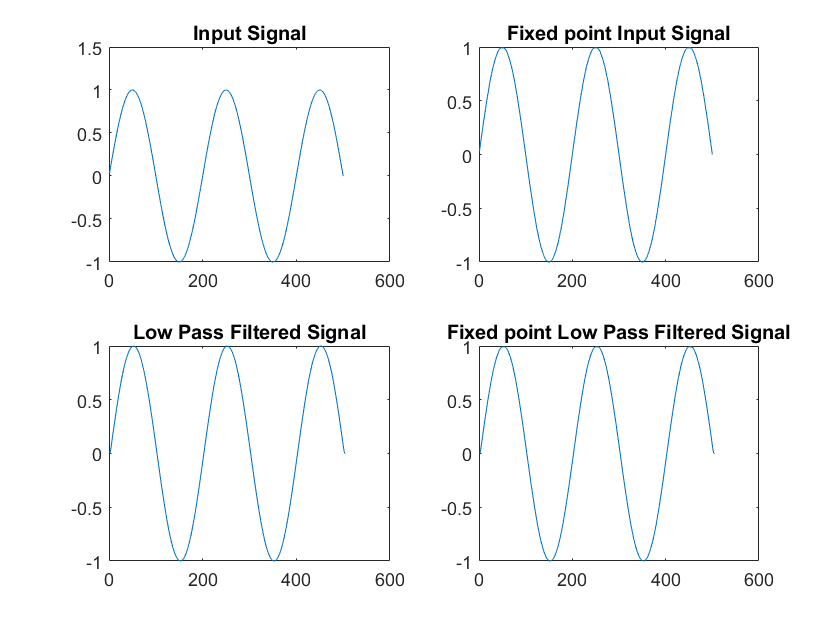


%% Input Signal
L=500; f1=10; f2=1500; f3=500;
sig=zeros(L,1);
for i=1:L
    sig(i)=sin(2*pi*f1*i/fs)+sin(2*pi*f2*i/fs)+sin(2*pi*f3*i/fs);
end
sig_fixed=fi(sig, 1, 8, 7);
%% Do convolution to get output signal
y=conv(sig,h);
y_fixed=conv(sig_fixed,h_fixed);
%% Plot input & output signal
figure(1)
subplot(2,2,1)
plot(sig)
title('Input Signal');
subplot(2,2,2)
plot(sig_fixed)
title('Fixed point Input Signal');
subplot(2,2,3)
plot(y)
title('Low Pass Filtered Signal');
subplot(2,2,4)
plot(y_fixed)
title('Fixed point Low Pass Filtered Signal');

%% Write fixed-point filter coefficients & input signal in hex format
file1=fopen('Filter Co-efficients from MATLAB.txt', 'w');
for i=1:1:length(h_fixed)
    hh=h_fixed(i)*2^8;
    if i<length(h_fixed)
        fprintf(file1, '%d, ', hh);
    else
        fprintf(file1, '%d', hh);
    end
end
fclose(file1);
file2=fopen('Input Signal Data from MATLAB.txt', 'w');
for i=1:length(sig_fixed)
    si=sig_fixed(i)*2^8;
    if i<length(sig_fixed)
        fprintf(file2, '%d, ', si);
    else
        fprintf(file2, '%d', si);
    end
end
fclose(file2);